- 시간 커팅 OK

- 값들만 나오면 됨 OK

- 데이터 포맷 한줄 OK

- 필터링 선택 스위치 OK

- plot을 위해서 main이 아닌 부위는 폭을 줄이기

- plot 에서 데이터 테이블로 뺴기

- SNR standard한 공식 log ....

# Part 1. Preview on single channel

mapping 하기 전에, 채널 하나에 대해서 전처리 과정이 어떻게 진행되는지 보겠습니다.

#### 1.데이터 읽어오기

보내주신 vertical 형식의 데이터를 읽어옵니다. 기존의 데이터와 다른 포맷이기 때문에 기존의 로딩 함수를 사용하지 않고 직접 channel object를 만듭니다.

코드를 보면 t를 등간격으로 만들기 위해 spline을 써서 resampling을 하는데, 이는 spike detection 알고리즘이 등간격을 가정하기 때문입니다.

데이터가 거의 등간격으로 수집되지만, 약간의 오차가 있기 때문에 resampling이 필요합니다. 오차가 아주 작기 때문에 signal 모양에는 변화가 거의 없습니다.

사용한 파일은 보내주신 파일에서 sheet 1만 따로 뺀 파일입니다.

raw_data = readmatrix("./data/2D mapping raw data(원본).xlsx"); %데이터 파일 읽어오기

size_of_data = size(raw_data); % 데이터 행과 열 개수
number_of_timestamp = size_of_data(1)-1; % 열 개수 - 1 = 측정 timestamp 개수
number_of_channel = size_of_data(2)-1; % 행 개수 - 1 = 채널 개수

%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(:,1); %시간 벡터를 따로 저장
sampleRateUsed = number_of_timestamp/(tVector(end) - tVector(1)) %sample rate 계산. 전체 시간을 관측치 개수로 나눔

channelNum = 1;
xVector = raw_data(:,1+1) % i번째 채널 데이터는 1+1번째 행에 있음
[xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
emg = channel(xResampled, tResampled, sampleRateUsed, 1, channelNum, 1);

### 전처리

#### 1. 시간 구간 자르기

cutTime method에 시간 구간을 벡터로 넣어 줍니다.

cutTime은 다른 모든 작업보다 먼저 해 주시기 바랍니다.

만약 작업을 하다가 시간 구간을 바꿔야 할 경우 데이터를 다시 불러온 다음 cutTime을 한 다음에 다른 작업을 진행해 주시기 바랍니다. 다른 작업을 한 다음에 cutTime을 하면 코드가 꼬입니다.

emg.cutTime([0.5,1])

new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209


#### 2. filtering

cutTime을 한 뒤에는 필터를 적용해 줍니다. Reference에 있는 대로 butterworth filter를 highpass와 notch로 걸어 주었는데, notch filter는 reference에 나온 데로 5th order로 하면 결과가 이상하게 나와서 2nd order로 하였습니다.

50hz를 필터링하기 위해 [49, 51] 구간을 제거하도록 하였습니다.

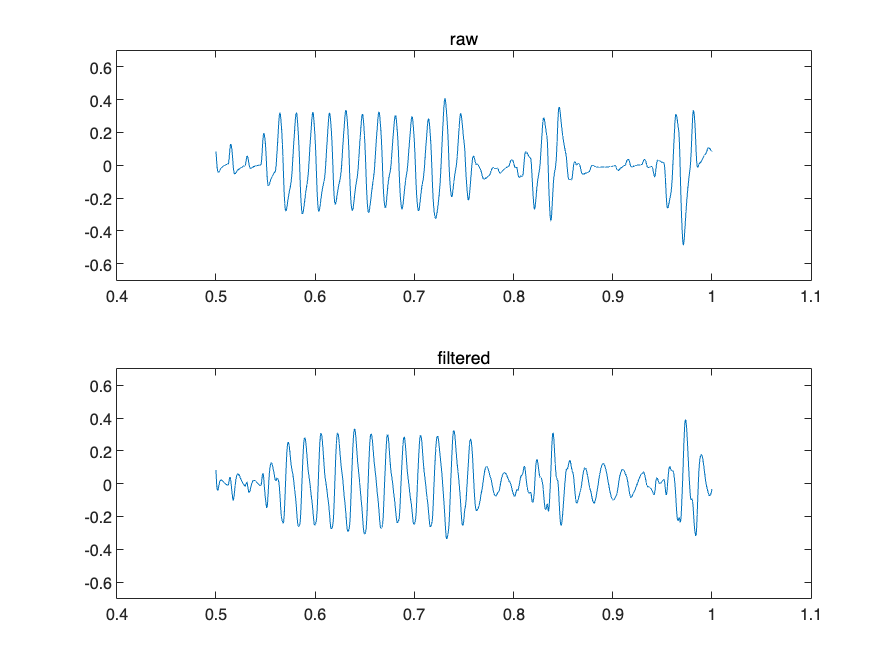

%                      order, cutoff frequency(Hz)
emg.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz

%                  order, cutoff frequency(Hz)interval
emg.notchButterworth(2, [49,51]) % 2th order Butterworth notch filter to reduce the noise at 50 Hz.

subplot(2,1,1);
plot(emg.t,emg.raw);
title("raw")
ylim([-0.7, 0.7])
subplot(2,1,2);
plot(emg.t,emg.filtered)
title("filtered")
ylim([-0.7, 0.7])

#### 3. rectification

rectification은 단지 신호값에 절댓값을 취하는 것에 불과하므로, 별도의 parameter를 입력할 필요가 없습니다.

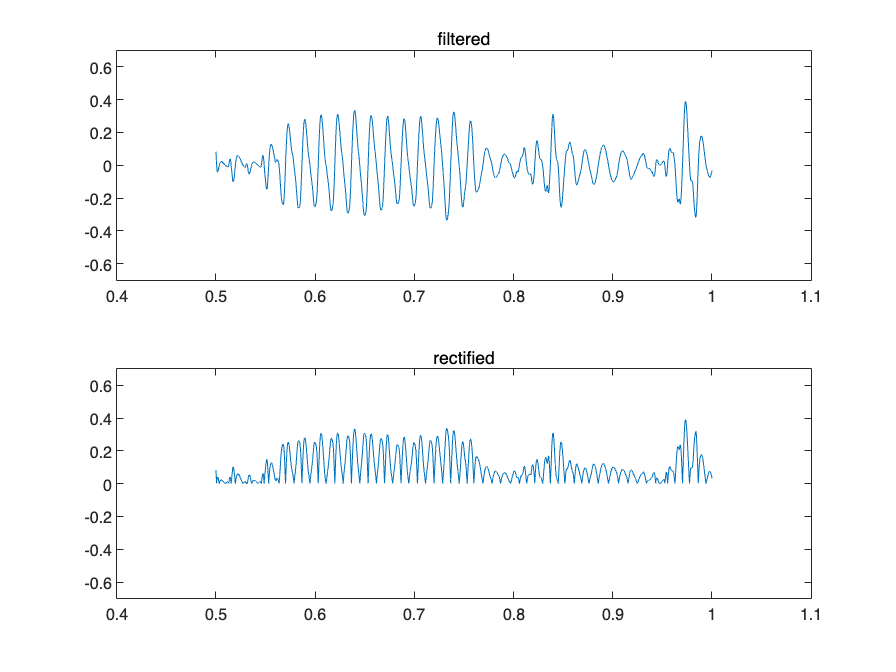

emg.rectify();

subplot(2,1,1);
plot(emg.t,emg.filtered);
title("filtered")
ylim([-0.7, 0.7])
subplot(2,1,2);
plot(emg.t,emg.signalFilteredRectified)
title("filtered and rectified")
ylim([-0.7, 0.7])

#### 4. enveloping(normalization)

matlab signal processing toolbox 설치가 필요합니다.

[https://kr.mathworks.com/help/signal/ref/envelope.html](https://kr.mathworks.com/help/signal/ref/envelope.html)

위의 함수를 사용하였습니다. 

필터 길이를 늘릴수록 더 부드러운 모양이 나옵니다.

enveloping은 rectification 단계에서 저장한 값을 변환하는 것이기 때문에, envelope를 다른 파라미터 값으로 다시 실행해도 됩니다. 즉 여러 필터 길이를 시도할 때 처음부터 다시 시작할 필요가 없습니다.

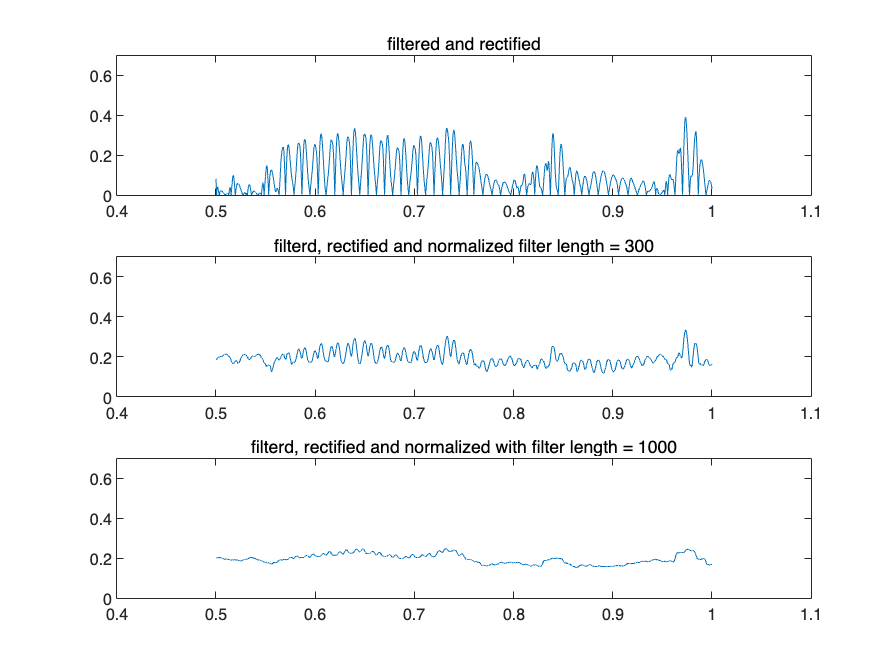

figure;

subplot(3,1,1);

plot(emg.t,emg.signalFilteredRectified);
title("filtered and rectified")
ylim([0, 0.7])

subplot(3,1,2);
%            필터 길이
emg.envelope(100)
plot(emg.t,emg.signalFilteredEnveloped)
title("filterd, rectified and normalized filter length = 300")
ylim([0, 0.7])

subplot(3,1,3);

%            필터 길이
emg.envelope(500)
plot(emg.t,emg.signalFilteredEnveloped)
title("filterd, rectified and normalized with filter length = 1000")
ylim([0, 0.7])

# Part 2. pixel mapping

EMG 데이터에 맞는 기능을 구현하기 위해, firing rate heatmap을 만드는  `timeVaryingHeatmap ``클래스를 수정하여 ``timeVaryingHeatmapEMG 클래스를 ``만들었습니다.`

`먼저 아래 코드로 ``timeVaryingHeatmapEMG ``오브젝트를 하나 만듭니다. 여기에 각 channel object를 넣고 전처리를 한 다음 heatmap을 그릴 것입니다.`

%                      nrow, ncol
ani = timeVaryingHeatmapEMG(5,5); % timeVaryingHeatmap 오브젝트 생성. pixel들이 5*5 배열로 되어 있다고 가정.

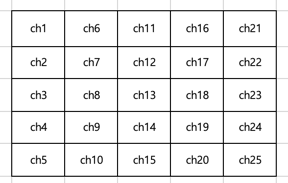

raw_data = readmatrix("./data/2D mapping raw data(원본).xlsx");

size_of_data = size(raw_data); % 데이터 행과 열 개수
number_of_timestamp = size_of_data(1)-1; % 열 개수 - 1 = 측정 timestamp 개수
number_of_channel = size_of_data(2)-1; % 행 개수 - 1 = 채널 개수

%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(:,1); %시간 벡터를 따로 저장
sampleRateUsed = number_of_timestamp/(tVector(end) - tVector(1)) %sample rate 계산. 전체 시간을 관측치 개수로 나눔

for i = 1 : number_of_channel %각 채널별로
    channelNum = i;
    column_number = fix((i-1)/5) + 1; %5로 나눈 몫 + 1이 column 번호

sampleRateUsed = 2.4414e+04


    row_number = rem(i,5); % 5로 나눈 나머지가 row 번호.
    if row_number == 0 %나머지가 0이면 row number = 5
        row_number = 5;
    end

    xVector = raw_data(:,i+1); % i번째 채널 데이터는 i+1번째 행에 있음
    [xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
                                                                %
    channel_now = channel(xResampled, tResampled, sampleRateUsed, 1, channelNum, 1);
    %  이 pixel의 row번호, column번호, pixel에 mapping할 channel 번호
    ani.addPixel(row_number, column_number, channel_now );
end

channel number = 1
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 1)th slot, added channel 1 


channel number = 2
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 1)th slot, added channel 2 


channel number = 3
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 1)th slot, added channel 3 


channel number = 4
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 1)th slot, added channel 4 


channel number = 5
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 1)th slot, added channel 5 


channel number = 6
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 2)th slot, added channel 6 


channel number = 7
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 2)th slot, added channel 7 


channel number = 8
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 2)th slot, added channel 8 


channel number = 9
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 2)th slot, added channel 9 


channel number = 10
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 2)th slot, added channel 10 


channel number = 11
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 3)th slot, added channel 11 


channel number = 12
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 3)th slot, added channel 12 


channel number = 13
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 3)th slot, added channel 13 


channel number = 14
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 3)th slot, added channel 14 


channel number = 15
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 3)th slot, added channel 15 


channel number = 16
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 4)th slot, added channel 16 


channel number = 17
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 4)th slot, added channel 17 


channel number = 18
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 4)th slot, added channel 18 


channel number = 19
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 4)th slot, added channel 19 


channel number = 20
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 4)th slot, added channel 20 


channel number = 21
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 5)th slot, added channel 21 


channel number = 22
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 5)th slot, added channel 22 


channel number = 23
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 5)th slot, added channel 23 


channel number = 24
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 5)th slot, added channel 24 


channel number = 25
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 5)th slot, added channel 25 


일괄 전처리

####  시간 구간 자르기

ani.cutTime([0.5, 1])


cutting the time of (1, 1)th element = channel 1
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (1, 2)th element = channel 6
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (1, 3)th element = channel 11
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (1, 4)th element = channel 16
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (1, 5)th element = channel 21
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (2, 1)th element = channel 2
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new nTimestamp = 12209

cutting the time of (2, 2)th element = channel 7
new startTime = 0.499999
new endTime = 1.000038
new duration = 0.500040
new n

#### filtering

notch filter는 signal 모양을 바꿔버리는 것으로 보입니다

처리가 제대로 되었는지 보기 위해 아무 픽셀이나 골라서 filtering 전후를 비교하는 그림을 그려보겠습니다.

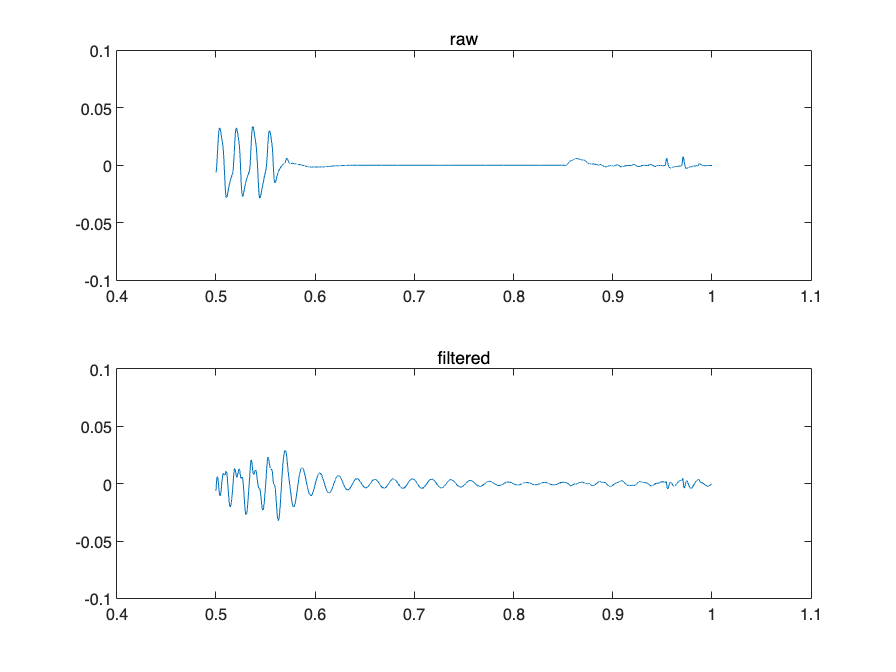

ani.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz
ani.notchButterworth(2, [49,51]) % 2th order Butterworth notch filter to reduce the noise at 50 Hz.


% test
figure;
subplot(2,1,1);
plot(ani.pixels{3,4}.t, ani.pixels{3,4}.raw);
title("raw")
ylim([-0.1, 0.1])
subplot(2,1,2);
plot(ani.pixels{3,4}.t, ani.pixels{3,4}.filtered)
title("filtered")
ylim([-0.1, 0.1])

rectify

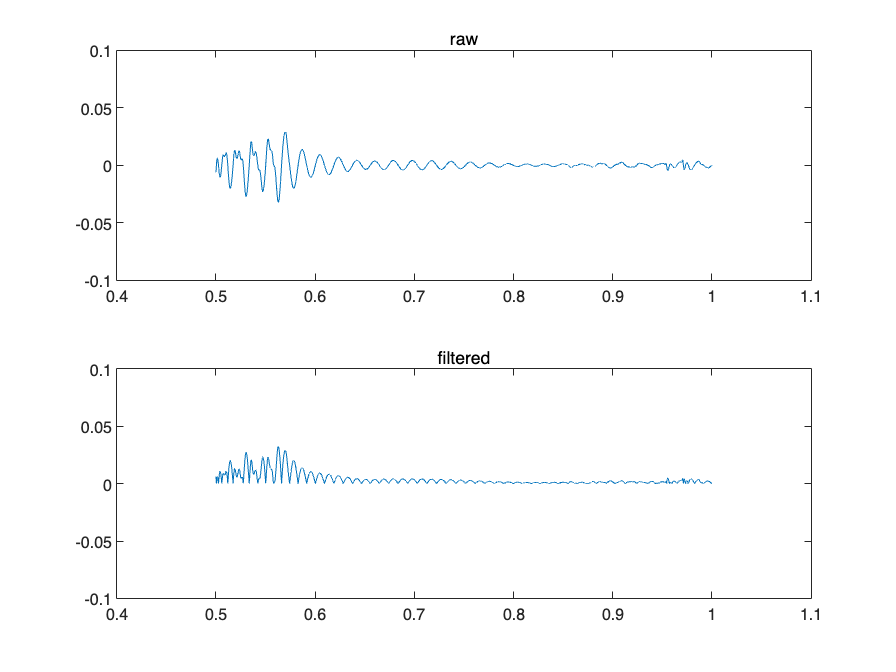

ani.rectify()

% test
figure;
subplot(2,1,1);
plot(ani.pixels{3,4}.t, ani.pixels{3,4}.filtered);
title("raw")
ylim([-0.1, 0.1])
subplot(2,1,2);
plot(ani.pixels{3,4}.t, ani.pixels{3,4}.signalFilteredRectified)
title("filtered and rectified")
ylim([-0.1, 0.1])

normalize

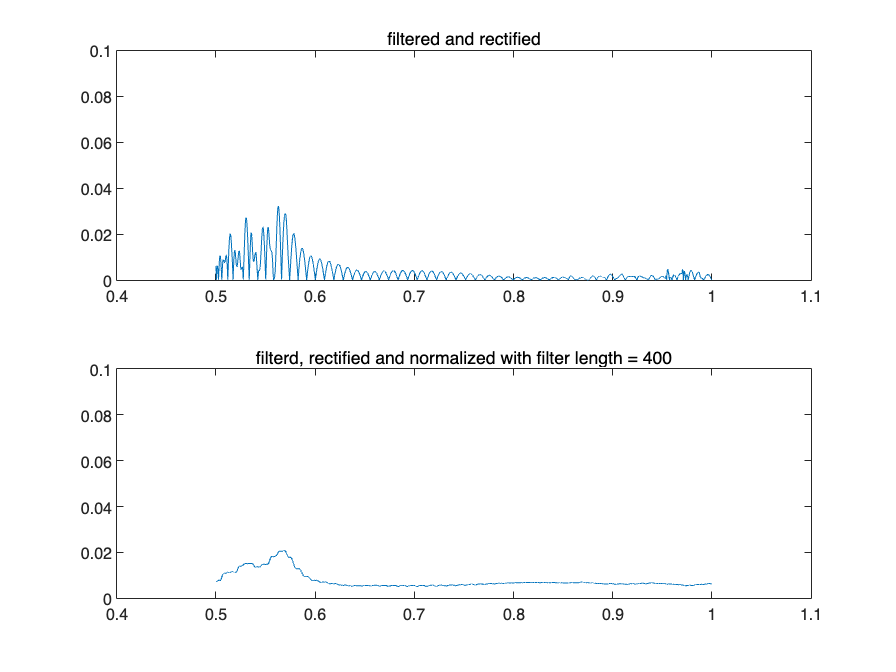

ani.envelope(400)
figure;

subplot(2,1,1);

plot(ani.pixels{3,4}.t,ani.pixels{3,4}.signalFilteredRectified);
title("filtered and rectified")
ylim([0, 0.1])

subplot(2,1,2);

%            필터 길이
plot(ani.pixels{3,4}.t,ani.pixels{3,4}.signalFilteredEnveloped)
title("filterd, rectified and normalized with filter length = 400")
ylim([0, 0.1])

heatmap 그리기

첫 번째 파라미터는 시간 간격입니다. 밀리세컨드 단위로 입력합니다.

두 번째 파라미터는 true/false로 filtered data를 사용할지, filtering하지 않은 데이터를 사용할지(rectify, normalize는 적용된 상태)를 결정합니다.

세 번째 파라미터는 heatmap의 colormap입니다. [https://kr.mathworks.com/help/matlab/ref/colormap.html#buq1hym](https://kr.mathworks.com/help/matlab/ref/colormap.html#buq1hym) 에서 colormap 목록을 확인할 수 있습니다.

아래 탐색 막대에서 배속을 조절할 수 있습니다. 배속 조절 버튼 옆의 버튼을 누르면 mp4 파일로 저장할 수도 있습니다.

step size = 244 timestamps = 9.994239 miliseconds
Total 50 steps
max signal value = 0.272032, ColorLimits is set w.r.t this value.

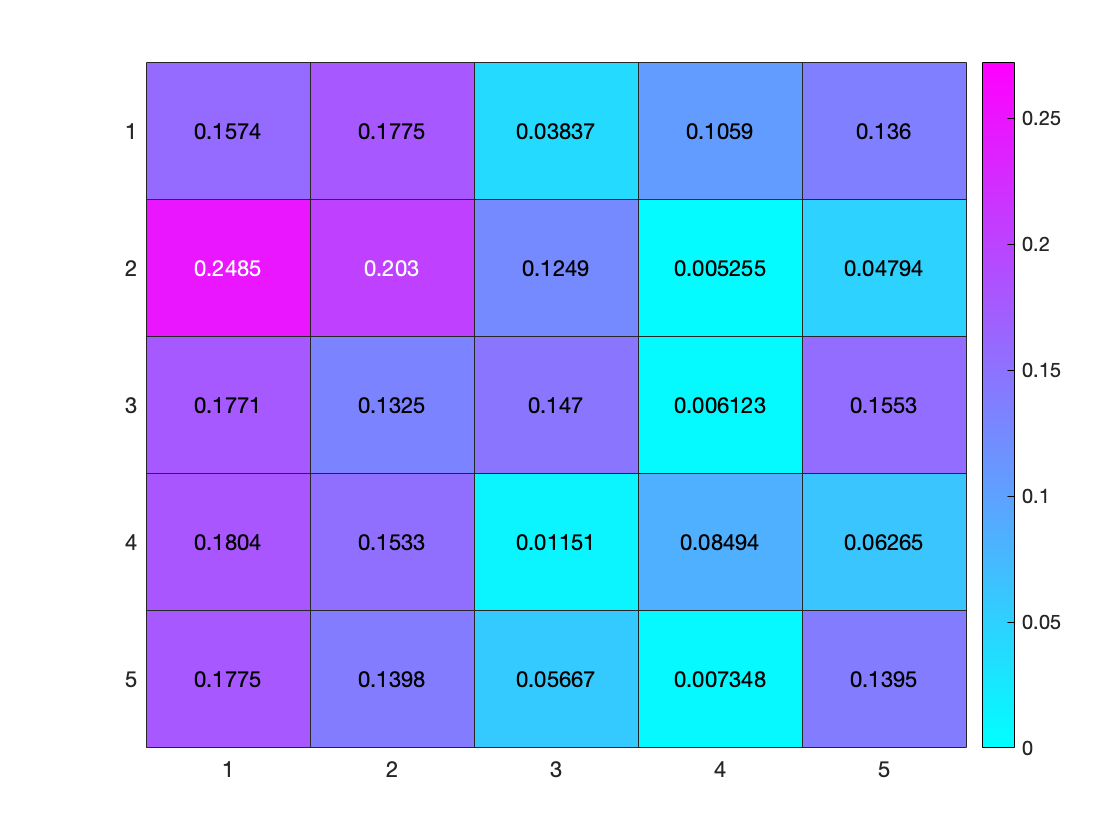

%                           
ani.makeTimeVaryingHeatmap( ...
    10, ... % 시간 간격(millisecond)
    true, ... % filterd or not
    cool) %colormap